by Ahmet Sacan.

## Introduction to Symbolic Math.

"Symbolic" or "algebraic" computations are carried out exactly, expressing the answer to a mathematical problem in a closed formula. The main task of a symbolic math system is to manipulate and simplify mathmetical expressions. These computations are carried out according to the rules of algebra, instead of approximate floating-point arithmetic used in "numerical" computations. 	

In Matlab, you can use sym() function to enforce symbolic computation rather than numerical computation.

Unfortunately, Matlab has decided to violate some programming language rules, such as independent and immediate evaluation of expressions, when implementing symbolic computation. e.g., in sym(1/3), matlab does not evaluate 1/3 first; it lets sym() function take 1/3 as is. And the rules Matlab follows seem arbitrary, so you should check small expressions to study the behavior of Matlab before incorporating them into larger expressions.

## Use sym() function to convert a number to a symbolic value.

sym( 1/3 )  % Matlab delays calculation of "/"

$$ans = \frac{1}{3}$$

sym( 10^1000 ) % Matlab does not delay calculation of "^"

$$ans = \infty$$

% to enforce symbolic computation reliably, enclose each number with sym().
sym(10)^sym(100)

$$ans = 10000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000$$

## Examples Demonstrating Symbolic Computation is Correct, but numerical Computation may not be

a = 1/3;
fprintf('%.70f\n',a)

0.3333333333333333148296162562473909929394721984863281250000000000000000


sym(1) / sym(3)

$$ans = \frac{1}{3}$$

10^1000 + 1 - 10^1000

ans = NaN

sym( 10^1000 + 1 - 10^1000 ) % this does not give correct symbolic result.

$$ans = \mathrm{NaN}$$

sym(10)^sym(1000) + sym(1) - sym(10)^sym(1000)

$$ans = 1$$

sin(pi)  % this is the regular sin() function, which produces an approximate numerical value.

ans = 1.2246e-16

sin(sym('pi'))  %this actually calls a different sin() function that is designed for symbolic math

$$ans = \sin\left(\pi \right)$$

factorial(1000)

ans = Inf

factorial(sym(100))

$$ans = 93326215443944152681699238856266700490715968264381621468592963895217599993229915608941463976156518286253697920827223758251185210916864000000000000000000000000$$

## Use syms() function to define a symbolic variable and create mathematical expressions with it

% You can define a variable to be symbolic. After that, the expressions
% involuving such symbolic variables become "mathmetical expressions",
% rather than numerical expressions that need to evaluate to a number.
syms x y
sqrt(x)

$$ans = \sqrt{x}$$

% Compare with a regular numerical variable:
t = 5;
sqrt( t )

ans = 2.2361

## Storing mathematical expressions in variables.

You can store a mathematical expresion in a variable. The variable you store into automatically becomes a symbolic variable (You do not need to declare it using syms()).

syms x
f = 5*x^2 + 3*x + 10

$$f = 5\,x^{2}+3\,x+10$$

% You can now use f, which will essentially be replaced with the
% mathematical expression it contains.
diff(f, x)

$$ans = 10\,x+3$$

## Converting a symbolic value to a numerical value: vpa() and double()

v = x * sqrt(56)

$$v = 2\,\sqrt{14}\,x$$

% Use vpa() to convert every occurence of a numerical expression to it
% calculated value.
vpa( v )

$$ans = 7.4833147735478827711674974646331\,x$$

vpa( v, 4 ) % You can specifiy the number of significant digits (default is 32)

$$ans = 7.483\,x$$

% if a symbolic expression does not contain any symbols, you can also use
% double() to convert it into a final numerical value.
v = sqrt(sym(56))

$$v = 2\,\sqrt{14}$$

vpa( v )

$$ans = 7.4833147735478827711674974646331$$

d = double( v )

d = 7.4833

fprintf('%.40f\n',d)

7.4833147735478826589883283304516226053238


## Calculus functions

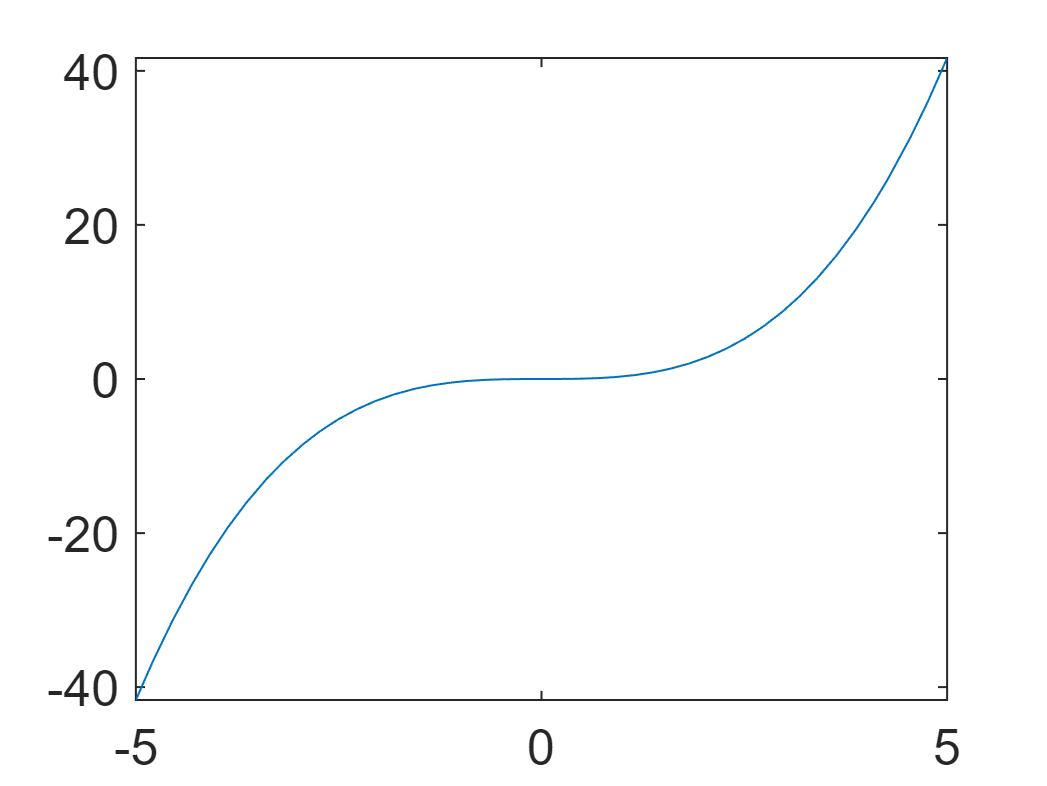

int(x^2, x)  % indefinite integral

int(x^2, x, sym(1), sym(4))  % definite integral

$$ans = 21$$

%sym() above was used just to be safe, but you'd get the same result
%without it for this example
int(x^2, x, 1, 4)

$$ans = 21$$

% Derivative: diff()
diff( sin(x^5) , x)

$$ans = 5\,x^{4}\,\cos\left(x^{5}\right)$$

% Second, third, etc. derivative can be taken by repeatedly calling diff()
diff( diff( sin(x^5), x), x)

$$ans = 20\,x^{3}\,\cos\left(x^{5}\right)-25\,x^{8}\,\sin\left(x^{5}\right)$$


% or by providing additional arguments to diff():
diff( sin(x^5) , x, x)

$$ans = 20\,x^{3}\,\cos\left(x^{5}\right)-25\,x^{8}\,\sin\left(x^{5}\right)$$

diff( sin(x^5) , x, x, x)

$$ans = 60\,x^{2}\,\cos\left(x^{5}\right)-125\,x^{12}\,\cos\left(x^{5}\right)-300\,x^{7}\,\sin\left(x^{5}\right)$$


% Limit
% e.g., find the limit of (1+1/n)^n while n goes to infinity:
syms n
limit((1 + 1/n)^n, n, sym(inf))

$$ans = \mathrm{e}$$

It may not be possible to reduce the expression to elementary functions (or Mupad may not be able to find it).

f = int(inv(exp(x^2) + 1), x)

$$f = \int \frac{1}{{\mathrm{e}}^{x^{2}}+1}\mathrm{d}x$$

But the differentiator recognizes that its derivative is the integrand:

diff(f, x)

$$ans = \frac{1}{{\mathrm{e}}^{x^{2}}+1}$$

Definite integrals may also be returned "unreduced"/"unsimplified"

v = int(inv(exp(x^2) + 1), x, sym(0), sym(1))

$$v = \int_{0}^{1}\frac{1}{{\mathrm{e}}^{x^{2}}+1}\mathrm{d}x$$

You can force calculation of a numerical value using vpa() or double()

double(v)

ans = 0.4195

Series Sum using **symsum()**

syms i n
symsum(i, i, sym(1), n)

$$ans = \frac{n\,\left(n+1\right)}{2}$$

symsum(i^2, i, sym(1), n)

$$ans = \frac{n\,\left(2\,n+1\right)\,\left(n+1\right)}{6}$$

## Simplifying / manipulating expressions

Use simplifyFraction() to find the common denominator for rational expressions and combine into a single ratio

f = x/(1 + x) - 2/(1 - x)

$$f = \frac{x}{x+1}+\frac{2}{x-1}$$

simplifyFraction(f)

$$ans = \frac{x^{2}+x+2}{\left(x-1\right)\,\left(x+1\right)}$$

simplifyFraction() will cancel out common factors between numerator and denominator in the result

syms x y
f = x^2/(x + y) - y^2/(x + y)

$$f = \frac{x^{2}}{x+y}-\frac{y^{2}}{x+y}$$

simplifyFraction(f)

$$ans = x-y$$

partfrac() (short for “partial fraction”) decomposes a rational expression into a sum of rational terms with simple denominators 

f = (x^2 + x + 2) / (x^2-1)

$$f = \frac{x^{2}+x+2}{x^{2}-1}$$

partfrac(f)

$$ans = \frac{2}{x-1}-\frac{1}{x+1}+1$$

simplify() tries to find a representation that is as "simple" as possible.

f = (exp(x) - 1) / (exp(x/2) + 1)

$$f = \frac{{\mathrm{e}}^{x}-1}{{\mathrm{e}}^{x/2}+1}$$

simplify(f)

$$ans = {\mathrm{e}}^{x/2}-1$$

factor() decomposes an expression into product of simpler ones:

terms = factor(x^3 + 3 * x^2 + 3 * x + 1)

$$terms = \left(\begin{array}{ccc} x+1 & x+1 & x+1 \end{array}\right)$$

terms(1)

$$ans = x+1$$

terms(2)

$$ans = x+1$$

terms(3)

$$ans = x+1$$

terms = factor(2 * x * y + -2 * x + -2 * y + x^2 + y^2)

$$terms = \left(\begin{array}{cc} x+y-2 & x+y \end{array}\right)$$

terms(1)

$$ans = x+y-2$$

terms(2)

$$ans = x+y$$

## Defining your own symbolic "functions" that can take in variables.

syms x a b
F = @(x) x^2

F = function_handle with value:
    @(x)x^2


F(5)

ans = 25

F(a + b)

$$ans = {\left(a+b\right)}^{2}$$

syms apple
F( apple )

$$ans = {\mathrm{apple}}^{2}$$

## Plotting with fplot()

The best part of plotting in Symbolic Math is you don't need to worry about providing x values. Matlab will use a range of [-5...5] by default.

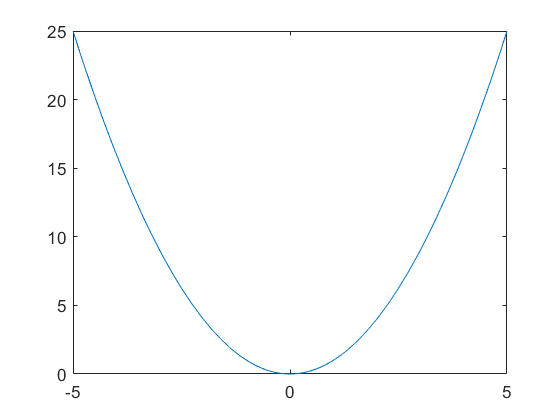

F = @(x) x.^2;
fplot(F)

You can specify the x axis range after fplot() is called. Matlab will automatically update the fplot.

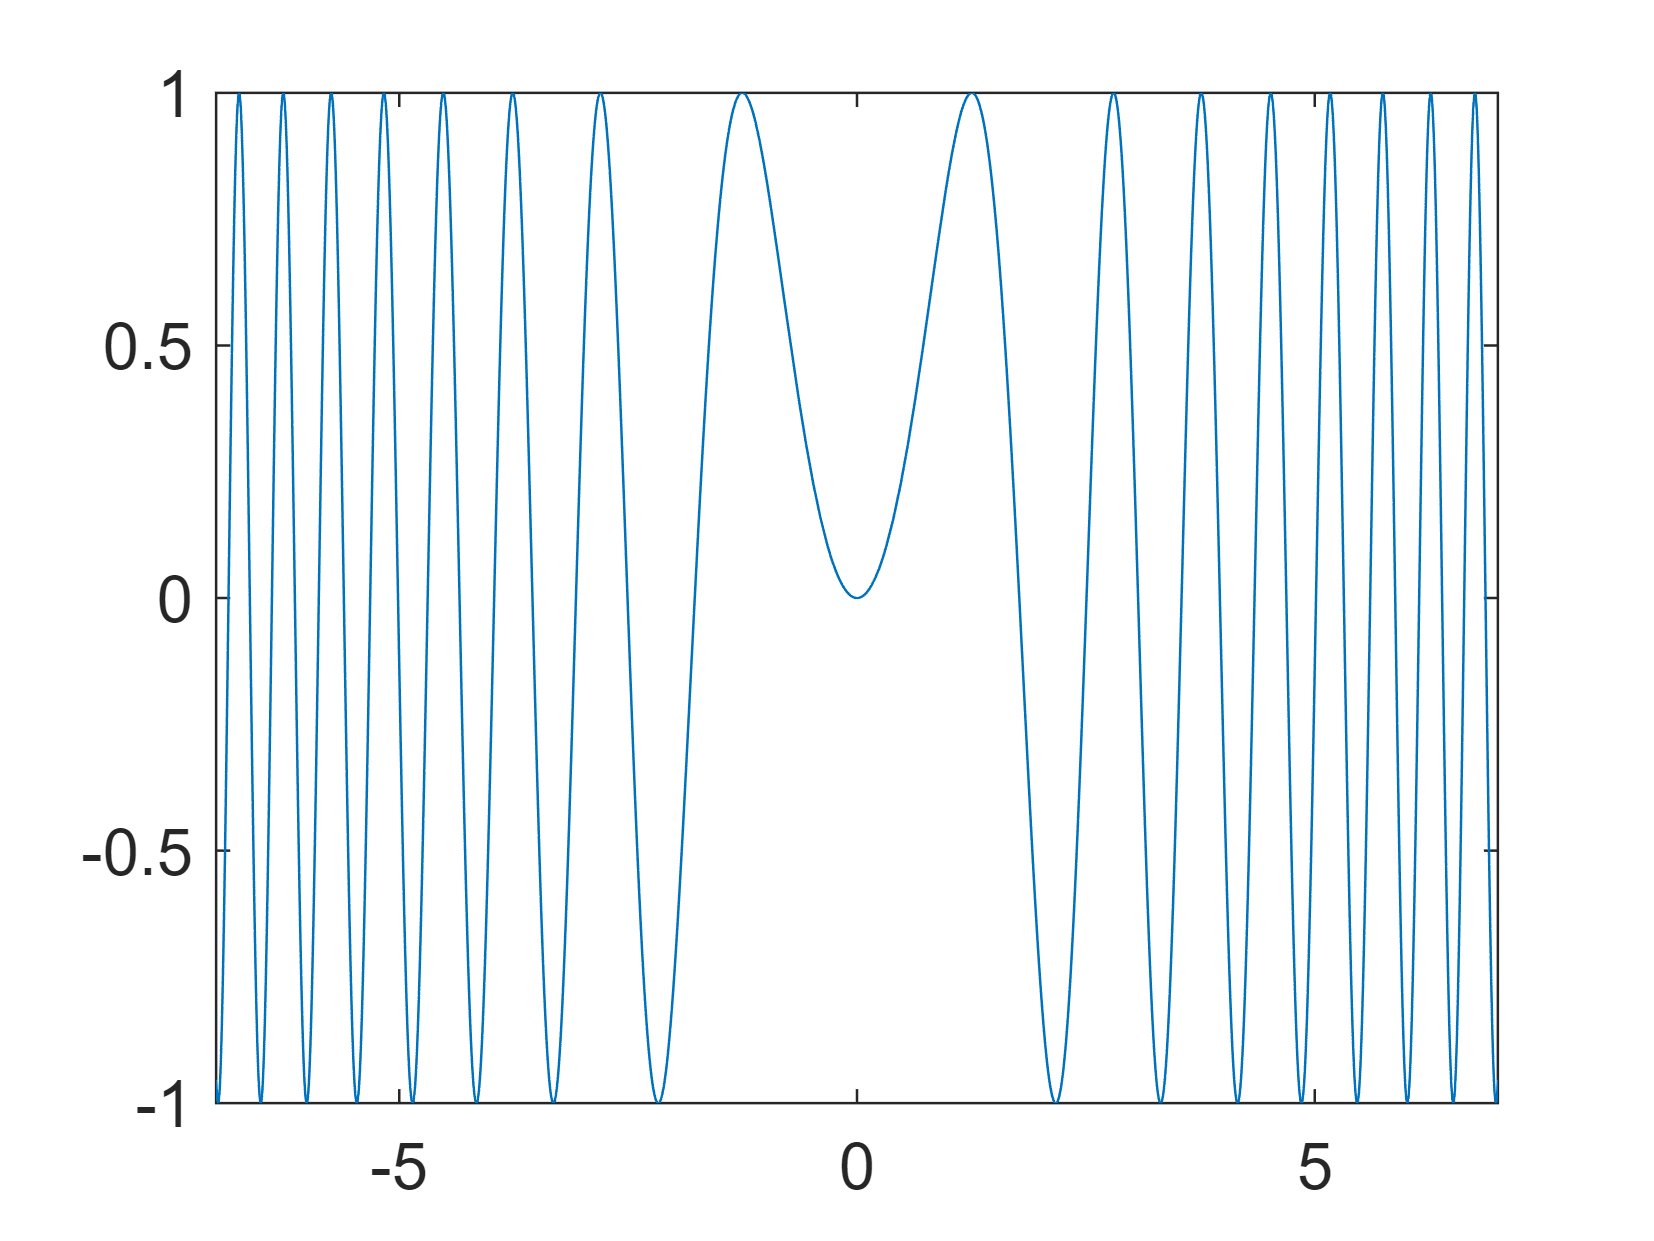

syms x
fplot(sin(x^2)) %a plot with x=[-5...5] would have been generated after this step.
axis([-7, 7, -Inf, Inf])

But the better method is to provide the range of x values when you call fplot()

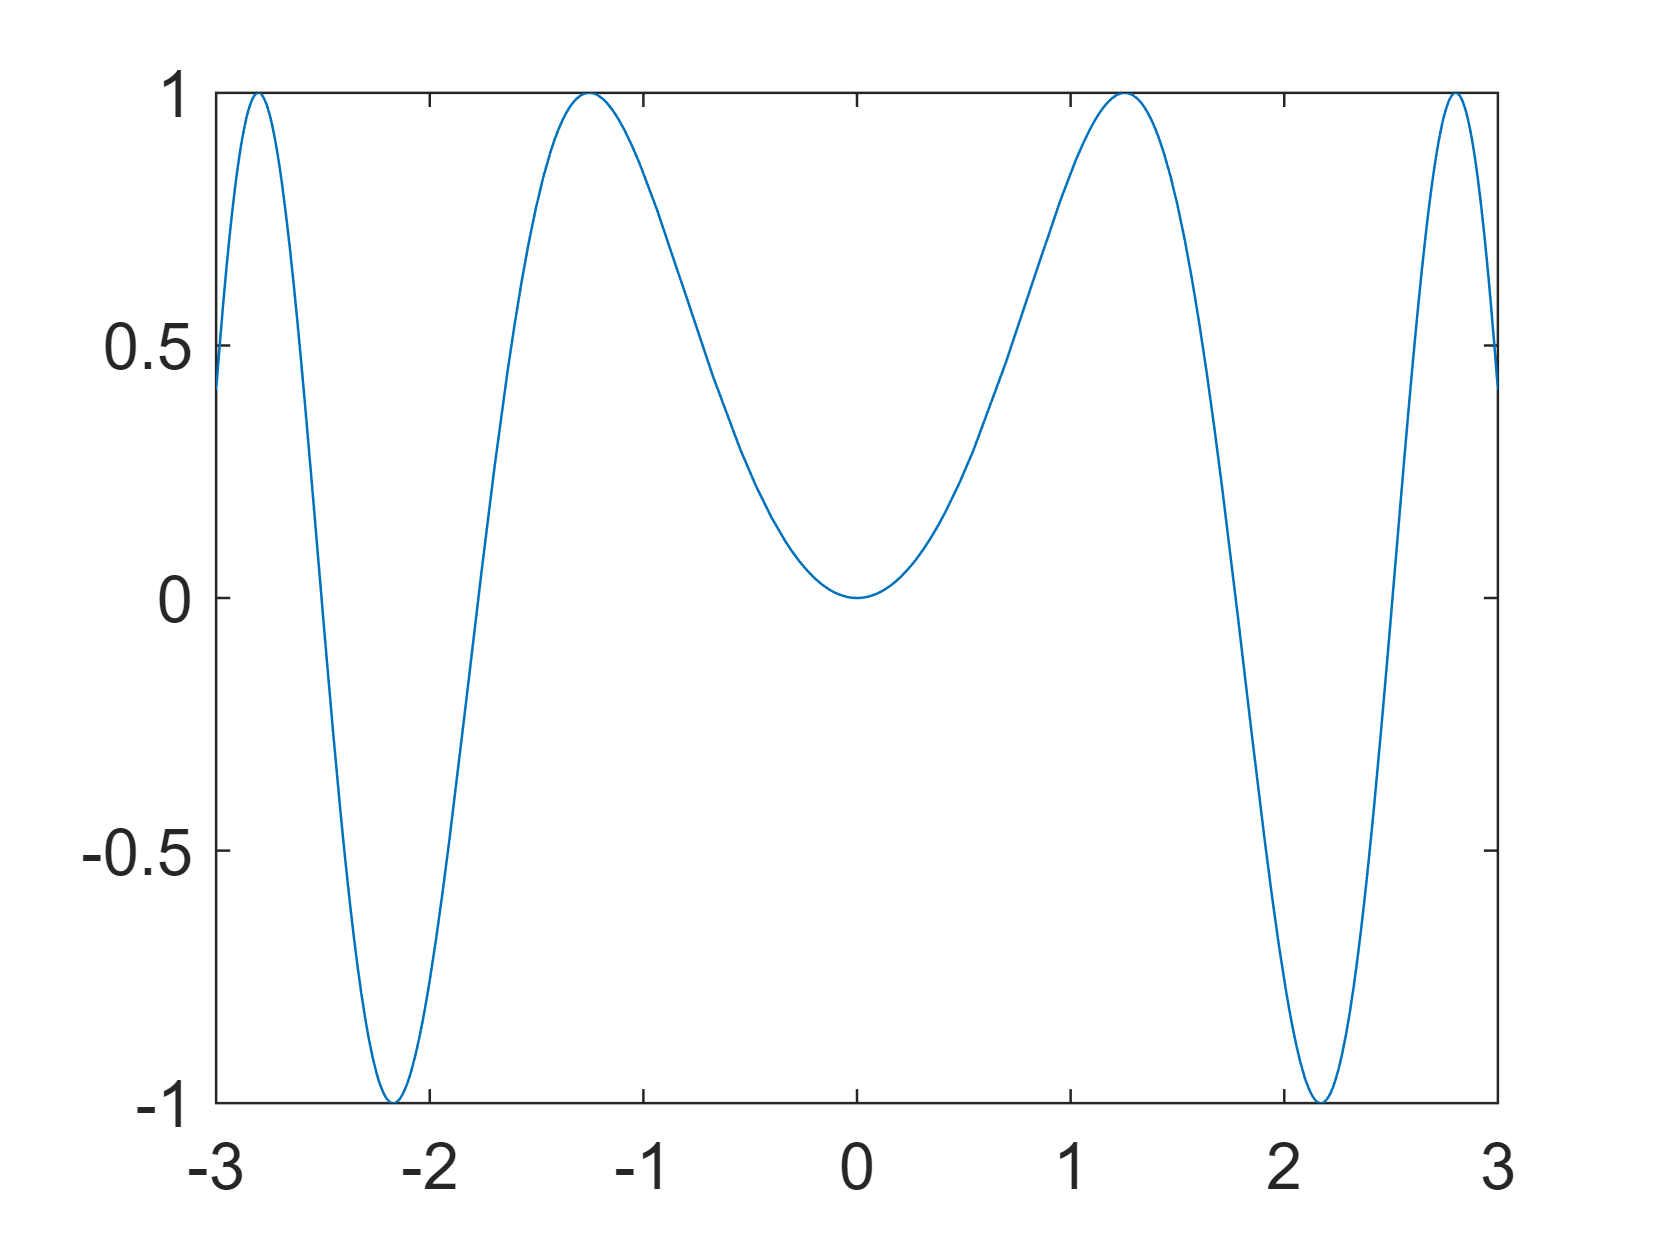

fplot(sin(x^2), [-3 3])

hold on/ hold off still work to create multiple plots on the same figure.

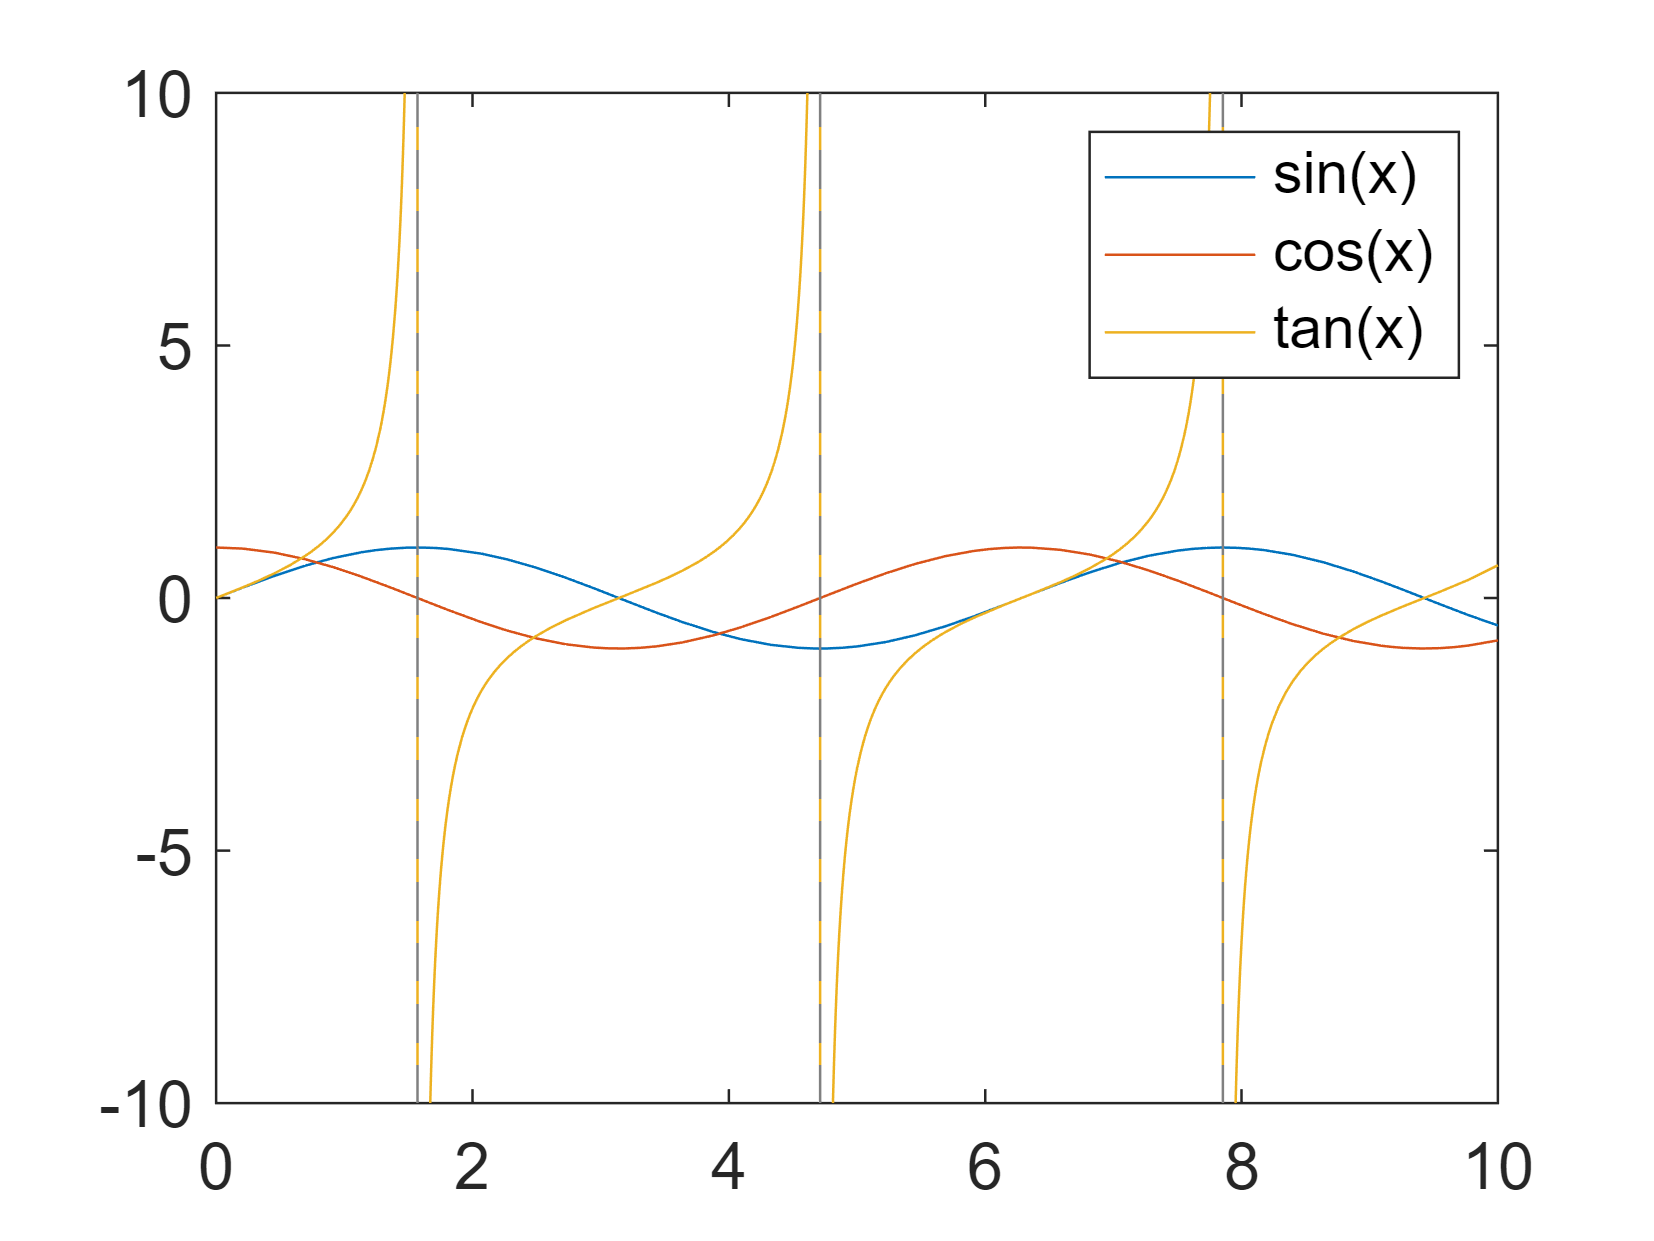

fplot(sin(x), [0, 10])
hold on
fplot(cos(x), [0, 10])
fplot(tan(x), [0, 10])
hold off;
% Matlab will automatically use the symbolic expressions as legends
legend show

If you don't like the default legends, use the "displayname" option.

Other usual options that you would use with plot() are still available with fplot().

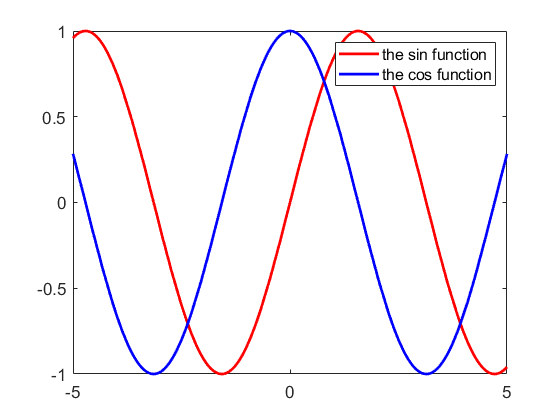

syms x
fplot(sin(x), 'displayname','the sin function', 'color',[1 0 0], 'linewidth',2)
hold on
fplot(cos(x), 'displayname','the cos function', 'color',[0 0 1], 'linewidth',2)
hold off
legend show

## Replacing variables in a symbolic expressions using subs()

syms a b c x
f = a * x^2 + b * x + exp(a) + c

$$f = a\,x^{2}+b\,x+c+{\mathrm{e}}^{a}$$

g = subs(f, {a}, {4})

$$g = 4\,x^{2}+b\,x+c+{\mathrm{e}}^{4}$$

g = subs(f, {a, b, c}, {4, 5, -9})

$$g = 4\,x^{2}+5\,x+{\mathrm{e}}^{4}-9$$

vpa( g, 4 )

$$ans = 4.0\,x^{2}+5.0\,x+45.6$$

## Solving Mathematical Equations using solve()

syms a b c
% Remember to use "==" when you express a symbolic equation.
solve(a * x + b == sym(0), x )

$$ans = -\frac{b}{a}$$

% "equals zero" is implied when it is not explicitly given
solve(a * x + b , x)

$$ans = -\frac{b}{a}$$

% if you omit what you are solving for, Matlab will guess it. Avoid this,
% as it can be reliable. It is better if you explicitly state what you are
% solving for.
solve(a * x + b )  % Avoid this.

$$ans = -\frac{b}{a}$$

% When solution contains multiple roots, the results will be available as a
% list. You can retrieve each root individually.
sol = solve(a * x^2 + b * x + c , x)

$$sol = \left(\begin{array}{c} -\frac{b+\sqrt{b^{2}-4\,a\,c}}{2\,a}\\ -\frac{b-\sqrt{b^{2}-4\,a\,c}}{2\,a} \end{array}\right)$$

sol(1)

$$ans = -\frac{b+\sqrt{b^{2}-4\,a\,c}}{2\,a}$$

sol(2)

$$ans = -\frac{b-\sqrt{b^{2}-4\,a\,c}}{2\,a}$$

The roots can be real & complex.

solve(x^4 + x^3 - x == sym(1), x)

$$ans = \left(\begin{array}{c} -1\\ 1\\ -\frac{1}{2}-\frac{\sqrt{3}\,\mathrm{i}}{2}\\ -\frac{1}{2}+\frac{\sqrt{3}\,\mathrm{i}}{2} \end{array}\right)$$

You can omit any non-real solutions:

solve(x^4 + x^3 + x * -1 == sym(1), x, 'Real', true)

$$ans = \left(\begin{array}{c} -1\\ 1 \end{array}\right)$$

Ignore unlikely edge cases with the IgnoreAnalyticConstraints option.

solve(log(y) + log(x + 1) == sym(1), y)

$$ans = \frac{\mathrm{e}}{x+1}$$

sol = solve(log(y) + log(x + 1) == sym(1), y, 'ReturnConditions',true)

sol = struct with fields:
             y: exp(1)/(x + 1)
    parameters: [1×0 sym]
    conditions: angle(x + 1) < pi


sol.y

$$ans = \frac{\mathrm{e}}{x+1}$$

sol.conditions

$$ans = \text{angle}\left(x+1\right)<\pi$$

solve(log(y) + log(x + 1) == sym(1), y, 'IgnoreAnalyticConstraints', true)

$$ans = \frac{\mathrm{e}}{x+1}$$

Sometimes there are infinite number of solutions:

solve(sin(x) == sym(1), x)

$$ans = \frac{\pi }{2}$$

To get only the "main" solution from the set, you can use the PrincipalValue option:

solve(sin(x) == sym(1), x, 'PrincipalValue', true)

$$ans = \frac{\pi }{2}$$

If you don't know which options to use Ignore and you are being lazy, try to use all. :)

solve(sin(x) == sym(1), x, 'Real', true, 'PrincipalValue', true, 'IgnoreAnalyticConstraints', true)

$$ans = \frac{\pi }{2}$$

## Solving systems of equations

The solve function can also be used to solve systems of equations. Simply specify the system of equations and the variables to solve for as vectors

% Multiple Equations can be specified as a list and solved simultaneously
syms x y
equations = [x + 2*y == 10,  x - y == 4]

$$equations = \left(\begin{array}{cc} x+2\,y=10 & x-y=4 \end{array}\right)$$

sol = solve(equations, [x y])

sol = struct with fields:
    x: [1×1 sym]
    y: [1×1 sym]


% You can retrieve individual variables:
sol.x

$$ans = 6$$

sol.y

$$ans = 2$$

### Another Example

syms x y a b
equations = [x + y == a ,  x - a * y == b]

$$equations = \left(\begin{array}{cc} x+y=a & x-a\,y=b \end{array}\right)$$

sol = solve(equations, [x y])

sol = struct with fields:
    x: [1×1 sym]
    y: [1×1 sym]


sol.x

$$ans = \frac{a^{2}+b}{a+1}$$

sol.y

$$ans = \frac{a-b}{a+1}$$

## Working with matrices

We follow Matlab conventions for row and column matrices: Use space or comma to separate within a row. Use semicolon to move onto the next row.

a = [1 x]

$$a = \left(\begin{array}{cc} 1 & x \end{array}\right)$$

b = [1; x]

$$b = \left(\begin{array}{c} 1\\ x \end{array}\right)$$

m =  [1 x; -x 1]

$$m = \left(\begin{array}{cc} 1 & x\\ -x & 1 \end{array}\right)$$

Linear Algebra operations can be done symbolically

syms a y z
A = [1 2; a, 4]

$$A = \left(\begin{array}{cc} 1 & 2\\ a & 4 \end{array}\right)$$

B = [y, 3; z, 5]

$$B = \left(\begin{array}{cc} y & 3\\ z & 5 \end{array}\right)$$

A + B

$$ans = \left(\begin{array}{cc} y+1 & 5\\ a+z & 9 \end{array}\right)$$

A * B

$$ans = \left(\begin{array}{cc} y+2\,z & 13\\ 4\,z+a\,y & 3\,a+20 \end{array}\right)$$

A^-1

$$ans = \left(\begin{array}{cc} -\frac{2}{a-2} & \frac{1}{a-2}\\ \frac{a}{2\,\left(a-2\right)} & -\frac{1}{2\,\left(a-2\right)} \end{array}\right)$$

% let's replace the constant a with 0.5
subs(A^-1, a, 0.5)

$$ans = \left(\begin{array}{cc} \frac{4}{3} & -\frac{2}{3}\\ -\frac{1}{6} & \frac{1}{3} \end{array}\right)$$

vpa( subs(A^-1, a, 0.5) , 4)

$$ans = \left(\begin{array}{cc} 1.333 & -0.6667\\ -0.1667 & 0.3333 \end{array}\right)$$

det(A) %determinant of matrix A

$$ans = 4-2\,a$$

## Solving system of equations in a matrix form.

In some cases, you may be able to express the system of equations in matrix form, .For these cases, you can use the linalg::matlinsolve function to solve the equations.

A = [1 3; 2 4]

A =      1     3
     2     4


b = [5; 6]

b =      5
     6


Let's solve Ax = b for x using mldivide "\" operation.

%use mldivide '\' operation instead of solve()
sol = A\b

sol =     -1
     2


Let's check if the answer is correct.

A * sol

ans =      5
     6


syms p q
sol = solve([1*p + 3*q == 5, 2*p + 4*q == 6], [p q])

sol = struct with fields:
    p: [1×1 sym]
    q: [1×1 sym]


sol.p

$$ans = -1$$

sol.q

$$ans = 2$$

## Solving Ordinary Differential Equations (ODEs)

You can solve various types of ordinary differential equations using the standard solve function (i.e. the same function that is used to solve algebraic equations) or the ode::solve function. If you use the standard solve function, you must first define your equation as an ODE. The same underlying algorithm is used regardless of which approach you choose.

First order differential equation example

% You must define y(t) as a symbol, rather than y and t separately.
syms y(t) a
eqn = diff(y, t) == a*y

$$eqn(t) = \frac{\partial }{\partial t}y\left(t\right)=a\,y\left(t\right)$$

dsolve(eqn)

$$ans = C_{1}\,{\mathrm{e}}^{a\,t}$$

2nd order linear ODE example

syms y(t) a
eqn = diff(y,t,2) + diff(y, t) + y(t) == 0

$$eqn(t) = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+\frac{\partial }{\partial t}y\left(t\right)+y\left(t\right)=0$$

dsolve( eqn )

$$ans = C_{1}\,{\mathrm{e}}^{-\frac{t}{2}}\,\cos\left(\frac{\sqrt{3}\,t}{2}\right)-C_{2}\,{\mathrm{e}}^{-\frac{t}{2}}\,\sin\left(\frac{\sqrt{3}\,t}{2}\right)$$

You can specify initial conditions and boundary conditions along with an ODE, which is often critical for real world problems in engineering and physics.

syms y(t)
eqn = diff(y,t,2) + diff(y,t) + y(t) == 0

$$eqn(t) = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+\frac{\partial }{\partial t}y\left(t\right)+y\left(t\right)=0$$

% in order to specify y'(0)=1, create Dy function first, and then specify
% Dy(0)==1 as a condition.
Dy = diff(y,t)

$$Dy(t) = \frac{\partial }{\partial t}y\left(t\right)$$

cond = [y(0) == 0,  Dy(0) == 1];
sol = dsolve(eqn, cond )

$$sol = \frac{2\,\sqrt{3}\,{\mathrm{e}}^{-\frac{t}{2}}\,\sin\left(\frac{\sqrt{3}\,t}{2}\right)}{3}$$

vpa(sol,4)

$$ans = 1.155\,{\mathrm{e}}^{-0.5\,t}\,\sin\left(0.866\,t\right)$$

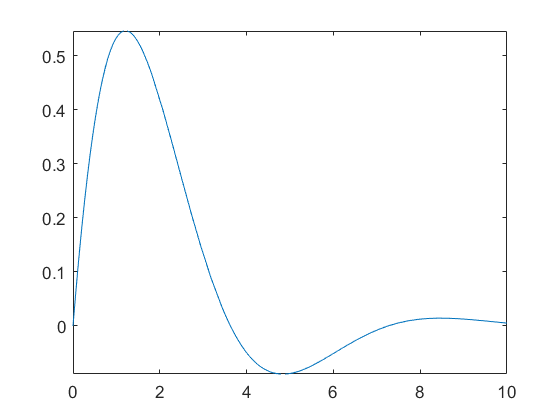

fplot( sol, [0, 10])

Another 2nd order ODE example

syms y(t)
Dy = diff(y,t)

$$Dy(t) = \frac{\partial }{\partial t}y\left(t\right)$$

D2y = diff(y,t,2)

$$D2y(t) = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)$$


eqn = D2y == 2*t/Dy

$$eqn(t) = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=\frac{2\,t}{\frac{\partial }{\partial t}y\left(t\right)}$$

cond = [y(0)==0, Dy(0)==1];
sol = dsolve(eqn, cond)

$$sol = \frac{\sqrt{2}\,\log\left(t+\sqrt{t^{2}+\frac{1}{2}}\right)}{4}-\frac{\sqrt{2}\,\log\left(\frac{\sqrt{2}}{2}\right)}{4}+\frac{\sqrt{2}\,t\,\sqrt{t^{2}+\frac{1}{2}}}{2}$$

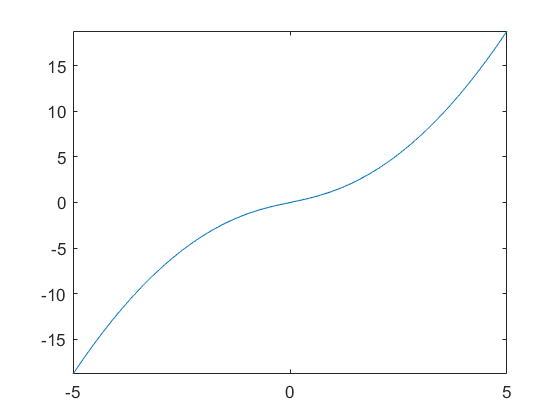

fplot(sol)

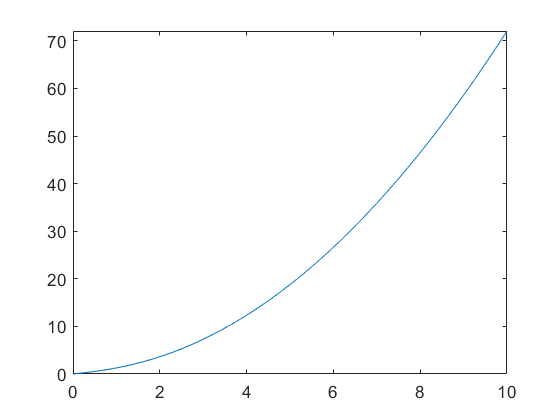

fplot( sol, [0,10])